
bpm_to_hertz = 1/60;

% 160 bpm to hertz
known_bpm = 160;

known_bpm * bpm_to_hertz

ans = 2.6667


% 100 readings per second
raw_data_160 = readtable('160_bpm.csv');
size(raw_data_160)

ans =         1834           5


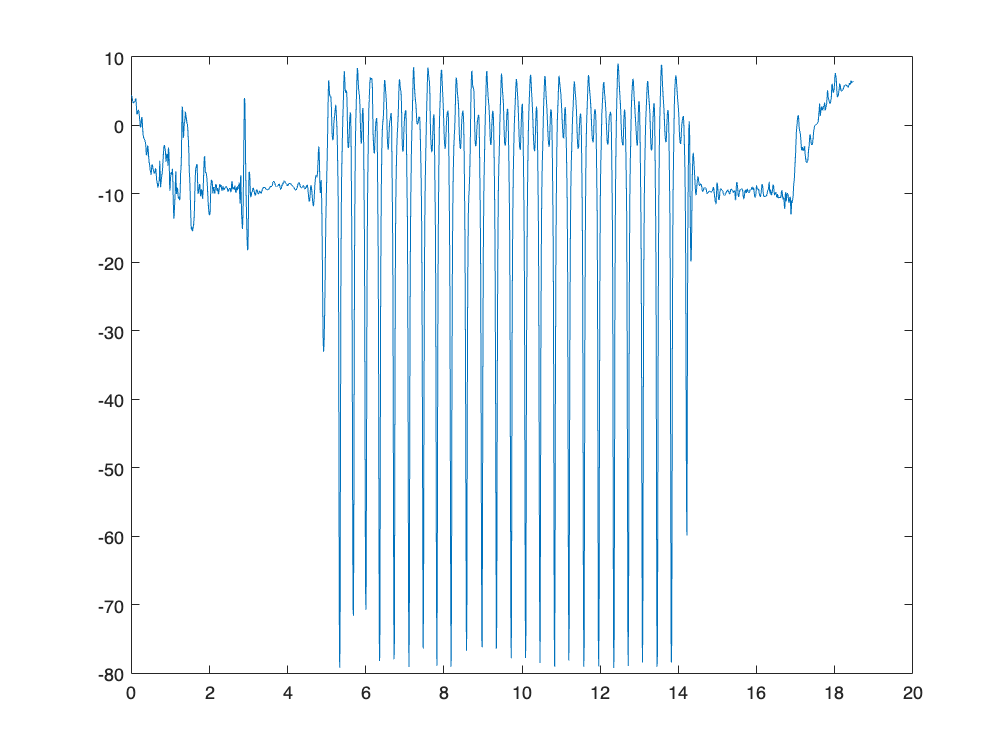

plot(raw_data_160.t, raw_data_160.a_y)

% trim data to time range
time_range = 550:1350;

time_range =    550   551   552   553   554   555   556   557   558   559   560   561   562   563   564   565   566   567   568   569   570   571   572   573   574   575   576   577   578   579   580   581   582   583   584   585   586   587   588   589   590   591   592   593   594   595   596   597   598   599


t_trim = raw_data_160.t(time_range);

t_trim =     5.5323
    5.5424
    5.5524
    5.5625
    5.5726
    5.5827
    5.5928
    5.6028
    5.6129
    5.6230


a_y_trim = raw_data_160.a_y(time_range);

a_y_trim =    -0.8549
   -2.9156
   -3.3331
   -3.1397
   -1.7675
    0.0901
    1.2599
    1.8641
    1.7210
   -2.2462


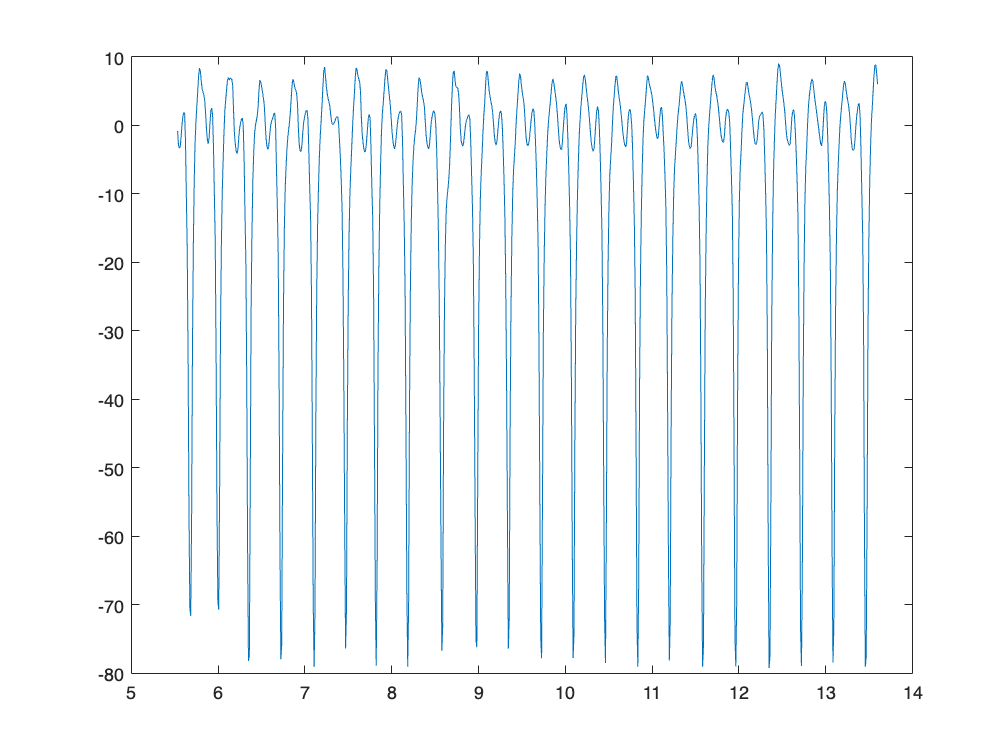

plot(t_trim, a_y_trim)

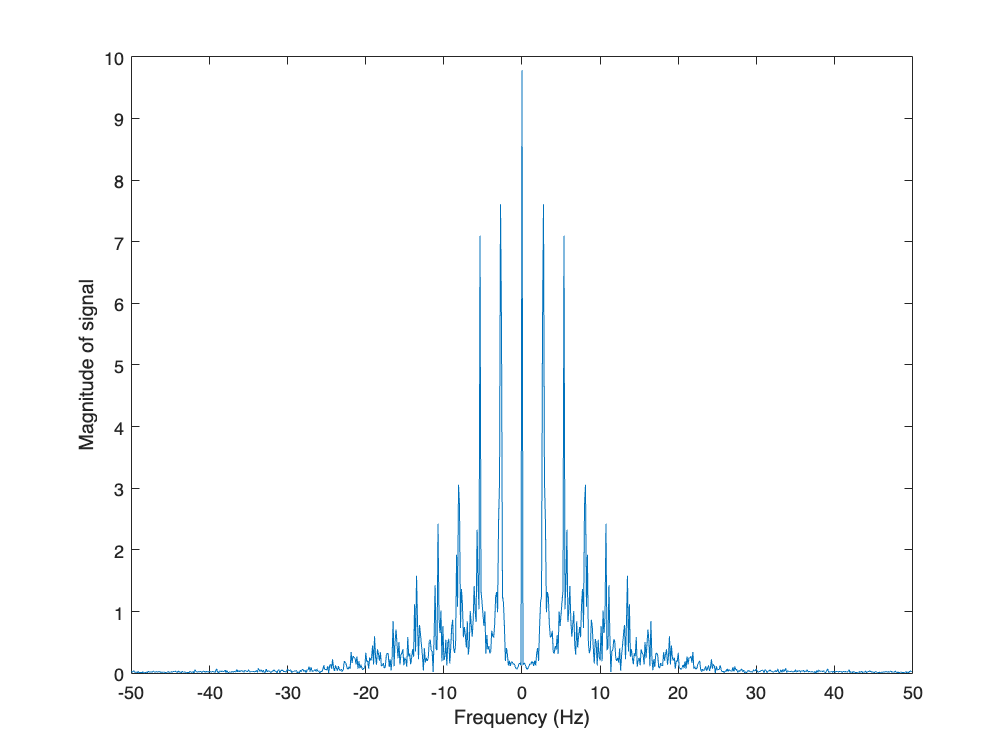

% sample fs is 100 hz
make_freq_plot(a_y_trim, 100)

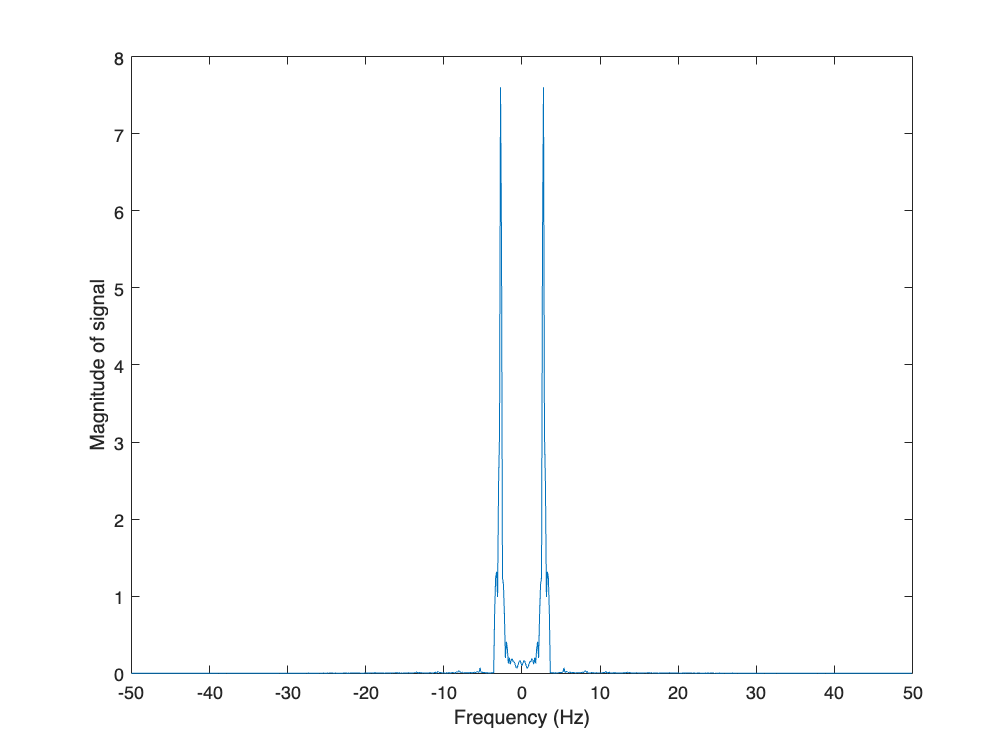

make_freq_plot_suppress(a_y_trim, 100)


% try to plot each peak as a sin graph and then compare, figure out which
% frequency it is supposed to be

% should filter out the frequencies that we aren't looking for
% take dft
dftx = fft(a_y_trim);

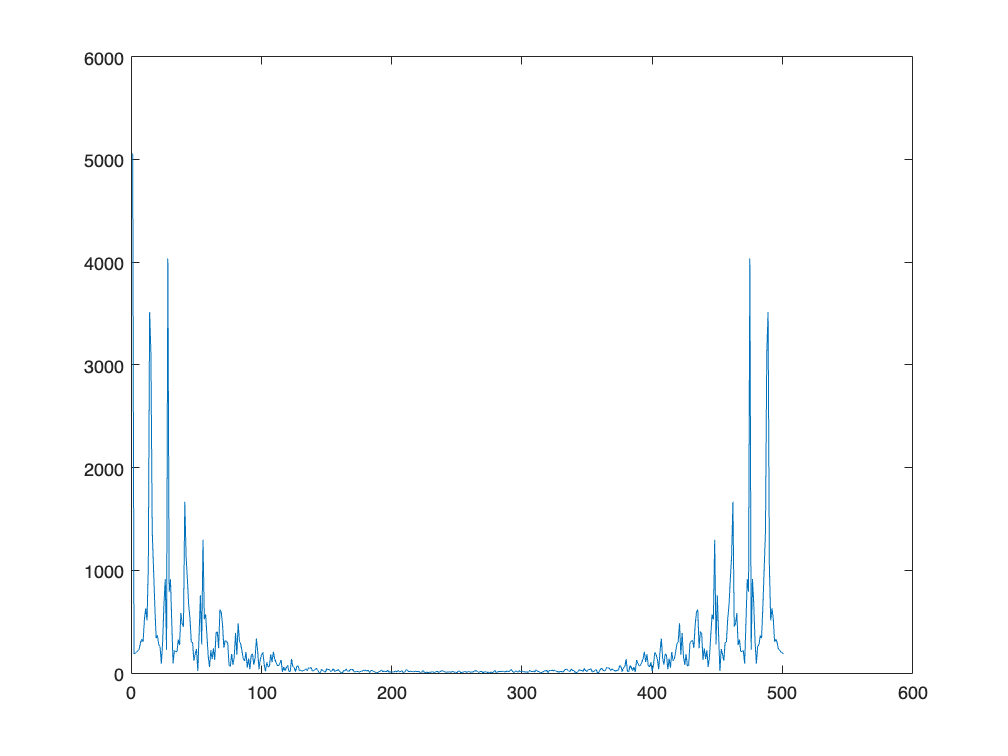

% plot dft
plot(abs(dftx))

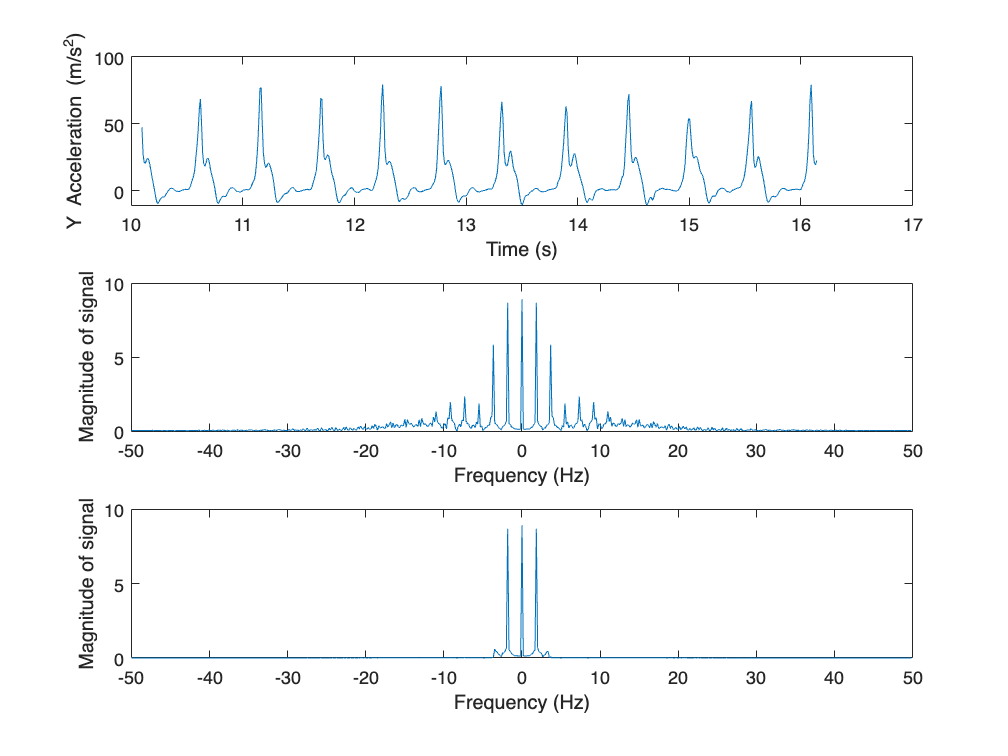

plotData('110_bpm.csv')
processData('110_bpm.csv', 110, 10, 16)

function plotData(csv_filename)
    raw_data = readtable(csv_filename);
    plot(raw_data.t, raw_data.a_y)
end

function processData(csv_filename, known_bpm, t_start, t_end)
    raw_data = readtable(csv_filename);
    t_trimmed = raw_data.t(t_start * 100:t_end * 100);
    a_y_trimmed = raw_data.a_y(t_start * 100:t_end * 100);

    % plot trimmed data
    subplot(3,1,1);
    plot(t_trimmed, a_y_trimmed)
    xlabel("Time (s)")
    ylabel("Y Acceleration (m/s^2)")
    
    % plot frequency graph without suppression
    subplot(3,1,2);
    make_freq_plot(a_y_trimmed, 100)

    % plot frequency graph, suppressed
    subplot(3,1,3);
    make_freq_plot_suppress(a_y_trimmed, 100)
end